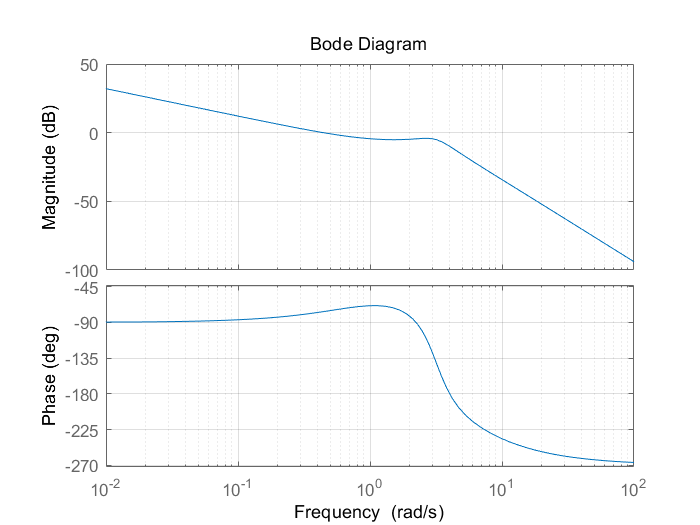

num = [20 20];
den = conv([1 5 0],[1 2 10]);
bode(num,den)
grid

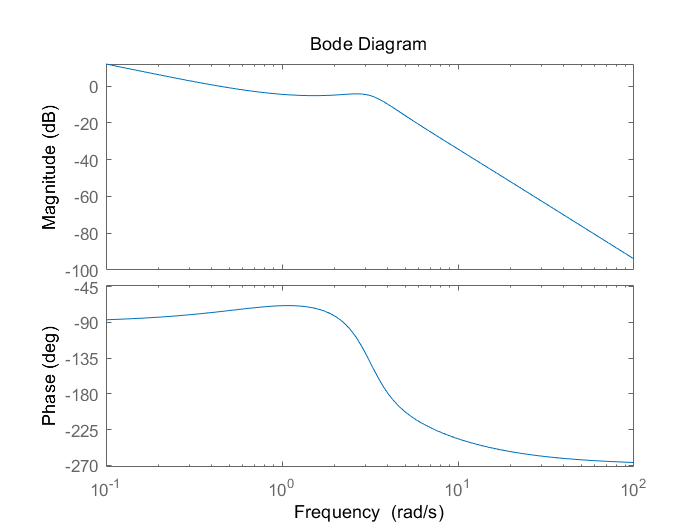

sys=tf(num,den);
w = logspace(-1,2,100);
bode(sys,w)

[Gm,Pm,wcp,wcg] = margin(sys);
GmdB = 20*log10(Gm);
[GmdB Pm wcp wcg];

syms s K w
% s = 1j*w;
G = (10*s+1)/(s^3+1.5*s^2+0.5*s);


num = [10,1];
den = [1, 1.5 0.5 0];
G1  = tf(num,den)


G1 =
 
        10 s + 1
  ---------------------
  s^3 + 1.5 s^2 + 0.5 s
 
Continuous-time transfer function.



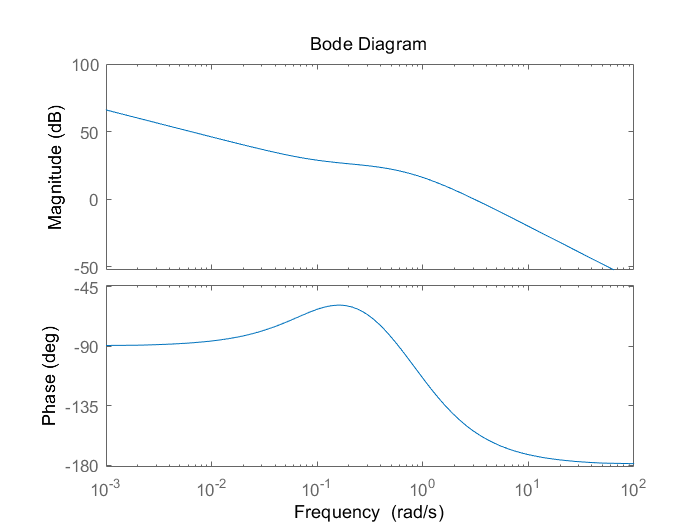

bode(G1)

% PM = 60;
% % w = 1.15;
% an = angle(G);
% a  = abs(G);
% exp1 = [a==1,an==-(180-PM)/(180/pi)];
% solu = vpasolve(exp1,[K,w]);
% [solu.K,solu.w]

% The SMC calculation of parameters
Beta = 1/6;
wn = 2000;
L = 900e-6;
C = 2300e-6;
sigma = 1.35;
Kp2 = wn^2*L*C

Kp2 =    8.279999999999999

Kp1 = Beta*L*2*wn*sigma

Kp1 =    0.810000000000000